# `Activity 6.1`

## `Spectrogram`

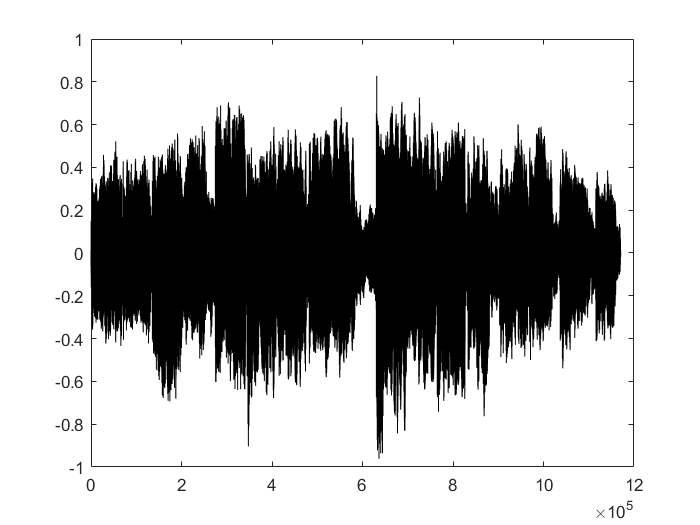

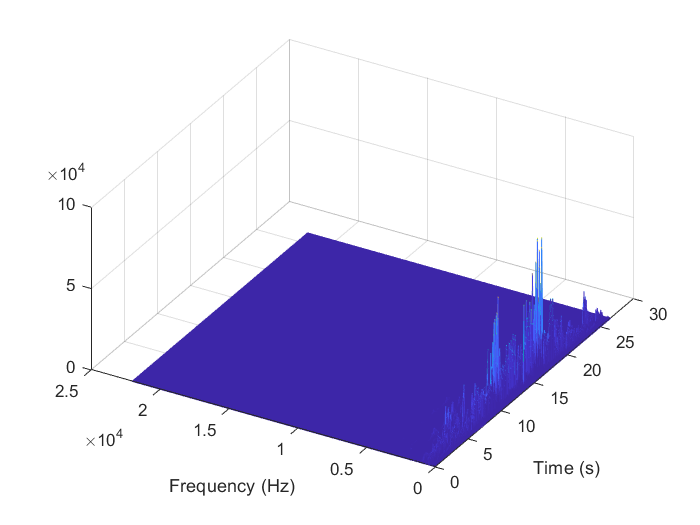

[x, Fs] = audioread('sarigamapa.wav');
x = x(:,1);
window_size = 2048;
hop_size = window_size/2;

[s,f,t] = spectrogram(x, window_size, hop_size,window_size,Fs,'yaxis');
waterplot(s,f,t)

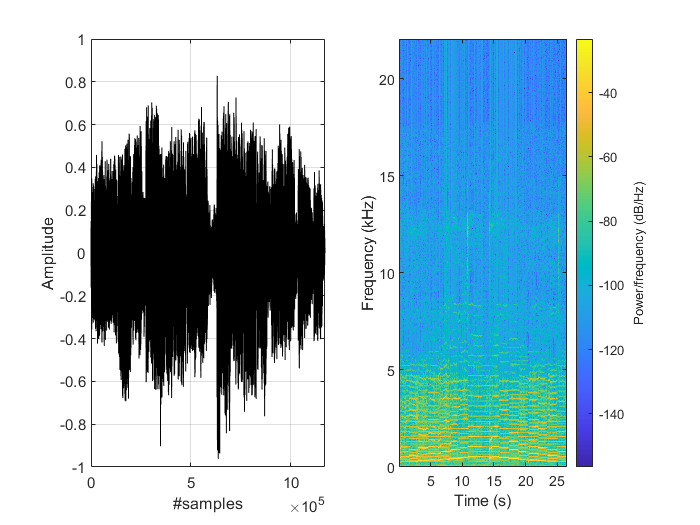

figure()
subplot(121)
plot(x,'k')
xlabel('#samples')
ylabel('Amplitude')
grid on

subplot(122)
spectrogram(x, window_size, hop_size,window_size,Fs,'yaxis');

### `Change Window`

hamming_window = window(@hamming,window_size); 
hanning_window = window(@hanning,window_size);
kaiser_window = window(@kaiser,window_size);
gausswin_window = window(@gausswin,window_size);

### `Visualization`

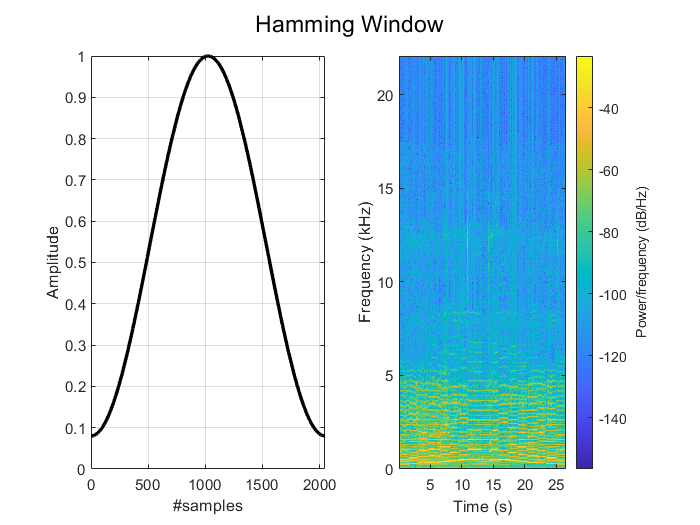

figure(1)
subplot(121)
plot(hamming_window,'LineWidth',2,'Color','k')
xlabel('#samples')
ylabel('Amplitude')
grid on
subplot(122)
spectrogram(x,hamming_window,hop_size,window_size,Fs,'yaxis');
sgtitle('Hamming Window')

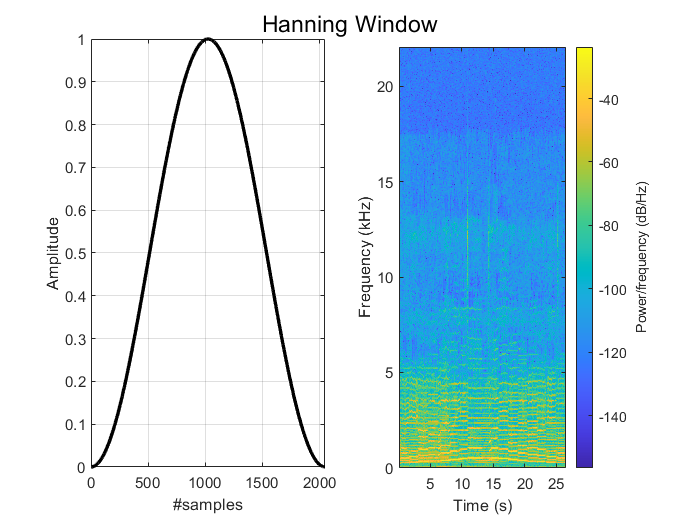


figure(2)
subplot(121)

plot(hanning_window,'LineWidth',2,'Color','k')
xlabel('#samples')
ylabel('Amplitude')
grid on
subplot(122)
spectrogram(x,hanning_window,hop_size,window_size,Fs,'yaxis');
sgtitle('Hanning Window')

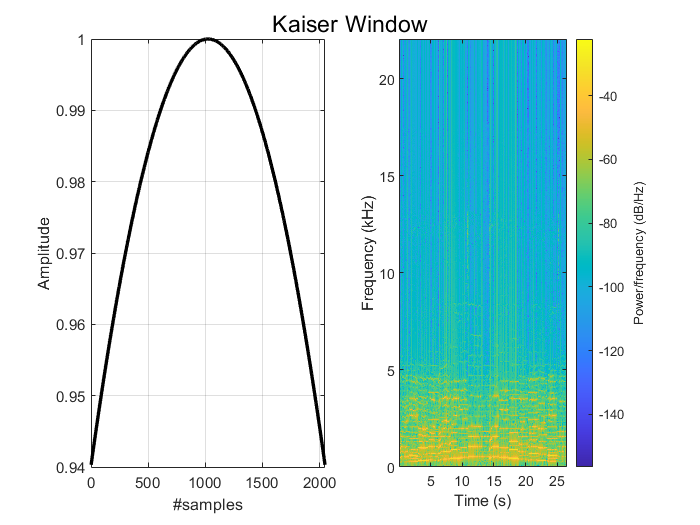


figure(3)
subplot(121)
plot(kaiser_window,'LineWidth',2,'Color','k')
xlabel('#samples')
ylabel('Amplitude')
grid on
subplot(122)
spectrogram(x,kaiser_window,hop_size,window_size,Fs,'yaxis');
sgtitle('Kaiser Window')

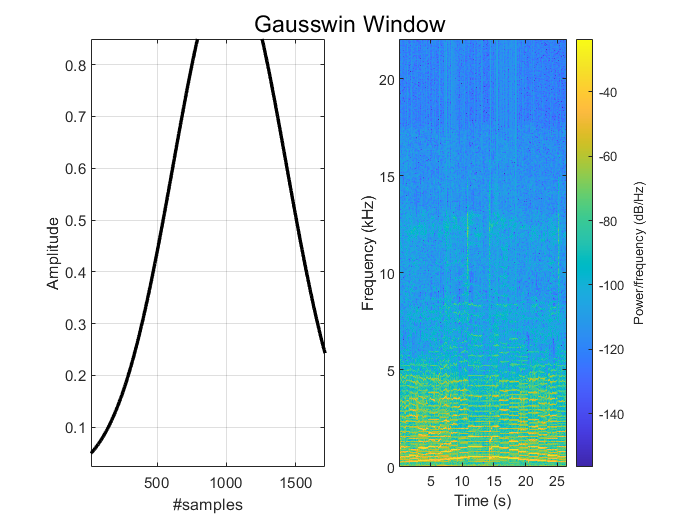


figure(4)
subplot(121)

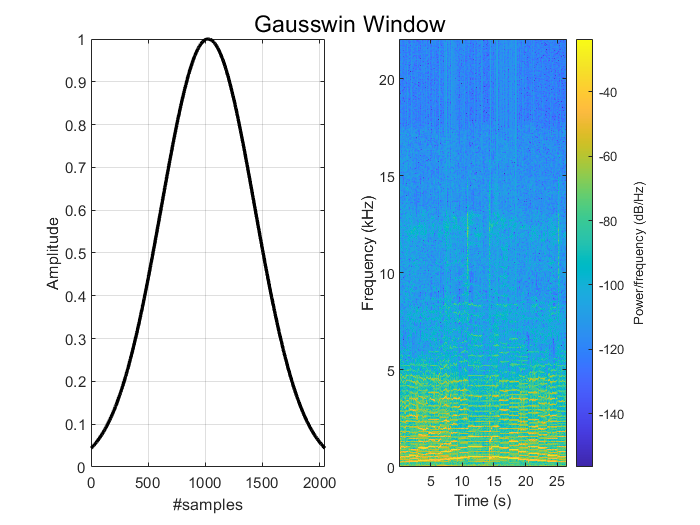

plot(gausswin_window,'LineWidth',2,'Color','k')
xlabel('#samples')
ylabel('Amplitude')
grid on

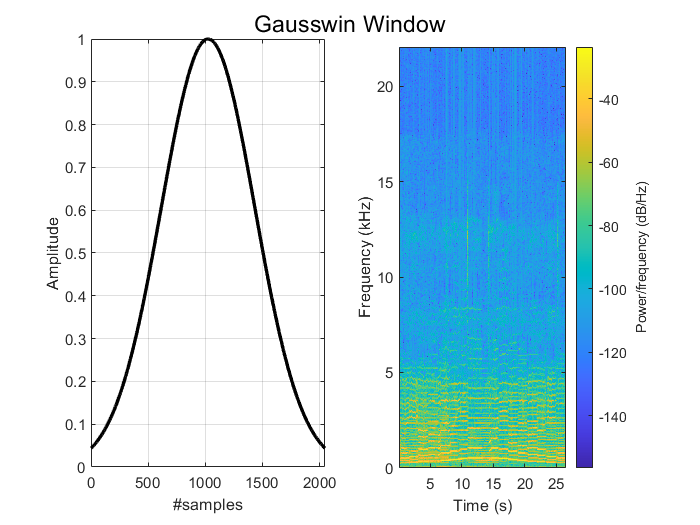

subplot(122)
spectrogram(x,gausswin_window,hop_size,window_size,Fs,'yaxis');
sgtitle('Gausswin Window')

### `Waterplot Function`

function waterplot(s,f,t)
% Waterfall plot of spectrogram
    waterfall(f,t,abs(s)'.^2)
    set(gca, 'XDir',"reverse", 'view',[30 50])
    xlabel("Frequency (Hz)")
    ylabel("Time (s)")
end